# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 10-Mar-2025 10:36:38

## Load Network Parameters

Load network parameters like weights, biases, or layers unusupported for network code generation from the the stored parameters file.

params = load(".\CNN_Norm.mat");

## Create Array of Layers

layers = [
    imageInputLayer([7 6 1], "Name", "input_1", "Normalization", "none")
    convolution2dLayer([3 3], 16, "Name", "conv", "Padding", "same")
    reluLayer("Name", "relu")
    fullyConnectedLayer(7, "Name", "fc")
    regressionLayer("Name", "regressionoutput")
];

## Plot Layers

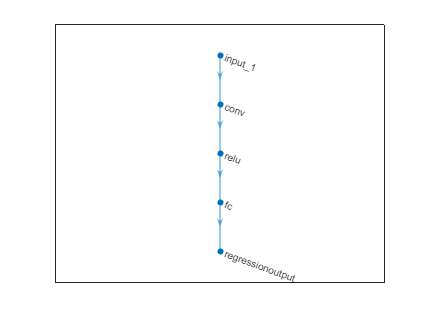

plot(layerGraph(layers));